# Linear Regressor Script

**Author: Surabhi Joshi**

Table of Contents

## Create the Dataset with a normal distribution

%Create a dataset
X = normrnd(0, 1, [20, 3]);
Y = normrnd(0, 1, [20, 3]);

## Split the data into Train and Test Sets

%shuffle the indices 
idx = randi(size(X,1),1,20);
% split the data - 80% of the data will be in the training sets. 

Xtrain = X(idx(1:10),:);
Ytrain = Y(idx(1:10),:);
Xtest = X(idx(11:20),:);
Ytest = Y(idx(11:20),:);

%initialize beta for linear regression
beta = randn([size(Xtrain, 2), 1]) * 0.001;
intercept = randn([size(Xtrain, 1), 1]) * 0.001;

alpha = 0.0001;
epochs = 10000;
MSE = zeros(epochs,1);
%learn with linear regression
for i = 1:epochs
    [ypred,MSE(i),dB,dInt] = lm(Xtrain, Ytrain, beta, intercept);
    
    beta = beta - (alpha .* dB');
    intercept = intercept - (alpha .* dInt);
end

## Plot MSE

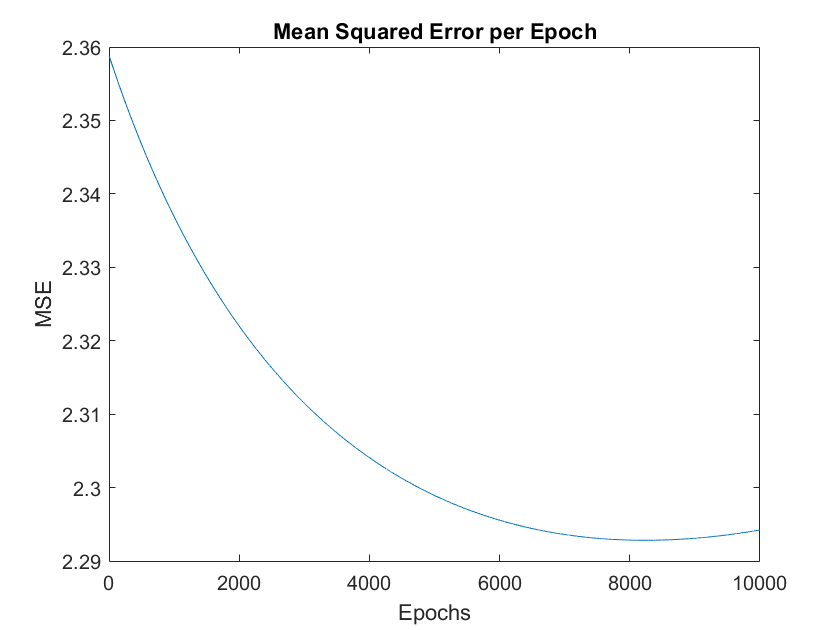

figure(1)
plot(MSE);
title('Mean Squared Error per Epoch');
ylabel('MSE')
xlabel('Epochs')

## Give a Final Prediction

model.y_final_pred = sum(intercept + (beta' .* Xtest ), 2);
model.mse = sum( mean((ypred - Ytrain) .^2) );
[pears, pval] = corr(ypred, Ytest);

model.beta = mean(beta);
model.intercept = intercept;
model.pval = mean(pval);
model.pears = pears;

## Cross Validate - Kfolds

%Cross Validation
kfolds = 10;
kfold_model = crossValidation(kfolds, X, Y);